% Load the selected features from the Excel file
selected_features = readmatrix('selected_eeg_features1.csv');

% Assume that you have labels for each epoch in a vector labels
% 1 for seizure and 0 for non-seizure. You need to create this labels
% vector as per your actual data.
% For demonstration, I'm creating a synthetic labels vector.
% It must have the same length as the number of epochs.
num_epochs_total = size(selected_features, 1);
labels = randi([0, 1], num_epochs_total, 1); % Random labels, replace with your actual labels

% Separate the features and the channel indices
channel_indices = selected_features(:, 1);
feature_data = selected_features(:, 2:end);

% Split the data into training and testing sets (80% training, 20% testing)
cv = cvpartition(labels, 'HoldOut', 0.2);
trainIdx = training(cv);
testIdx = test(cv);

% Training data
X_train = feature_data(trainIdx, :);
y_train = labels(trainIdx);

% Testing data
X_test = feature_data(testIdx, :);
y_test = labels(testIdx);

% Train the SVM classifier with a linear kernel
SVMModel = fitcsvm(X_train, y_train, 'KernelFunction', 'linear', 'Standardize', true);

% Predict the labels for the test set
y_pred = predict(SVMModel, X_test);

% Evaluate the classifier performance
accuracy = sum(y_pred == y_test) / length(y_test);
confMat = confusionmat(y_test, y_pred);

fprintf('Model Accuracy: %.2f%%\n', accuracy * 100);

Model Accuracy: 57.06%


disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    36    49
    24    61


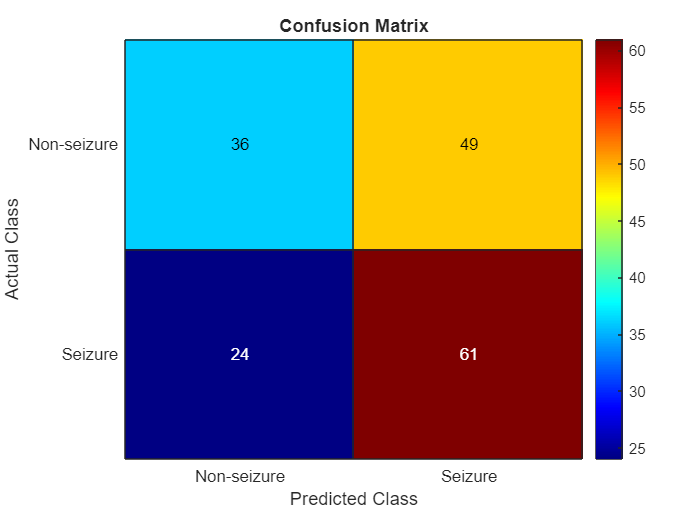


% Visualize the confusion matrix
figure;
heatmap({'Non-seizure', 'Seizure'}, {'Non-seizure', 'Seizure'}, confMat, ...
        'Colormap', jet, 'ColorbarVisible', 'on');
title('Confusion Matrix');
xlabel('Predicted Class');
ylabel('Actual Class');


% Save the trained model
save('SVMModel1.mat', 'SVMModel');
disp('SVM model saved as SVMModel.mat');

SVM model saved as SVMModel.mat
